# Dynamic Time Warping Sample Frequency Investigation

This script aims to investigate the effect of varying the resampling rate on the qualitative winner of a Dynamic Time Warping distance measure comparison between a state space integral controller and a state space PID controller. The same control responses are used for the different resample frequencies. It may be adpated to include the effects of total test time on the outcome. 

addpath('Classes')
addpath('Simulink Models')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

if (~exist('LMSPC_Int_x', 'var'))
    
    %Create an object of the class Lin_Mvng_Stpt_Cntr_SS
    LMSPC_Int_x = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, VDefs, 'SS Integral Controller x dimension');

    %Place its poles
    K_Int = place(double(LMSPC_Int_x.sys_mats.Aa),double(LMSPC_Int_x.sys_mats.Ba), [-10 -20 -30 -4 -5]); 

    %Moving Setpoint Parameters
    r_sim = 50; % radius of circular trajectory [mm]
    omega_sim =  2*pi/4; %angular frequency of circular trajectory   
    
    %%Create symbolic function from the desired trajectory information
    des_traj_sym_Int_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
    %Overlay a fist order response so that the desired trajectory is smoothed out a bit
    T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
    des_traj_sym_Int_x(VDefs.t) = (1 - exp(-(VDefs.t/T)))*des_traj_sym_Int_x;

    %%Simulate the Integral Controller
    %Specify simulation time
    tspan = [0 2*pi/omega_sim];
    %Specify initial conditions
    xa_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
    LMSPC_Int_x.Run_Sim(des_traj_sym_Int_x, tspan, xa_0, K_Int);

end

if (~exist('LMSPC_PID_x', 'var'))
    
    %Create an object of the class Lin_Mvng_Stpt_Cntr_SS
    LMSPC_PID_x = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, VDefs, 'SS PID Controller x dimension');
    
    %%Place its poles
    K_PID = place(double(LMSPC_PID_x.sys_mats.Aa),double(LMSPC_PID_x.sys_mats.Ba), [-10 -20 -30 -4 -5]); 
    
    %%Create symbolic function from the desired trajectory information
    des_traj_sym_dot_Int_x(VDefs.t) = diff(des_traj_sym_Int_x(VDefs.t),VDefs.t);
    des_traj_sym_ddot_Int_x(VDefs.t) = diff(des_traj_sym_Int_x(VDefs.t),VDefs.t,2);
    des_traj_sym_PID_x = [des_traj_sym_Int_x;des_traj_sym_dot_Int_x;des_traj_sym_ddot_Int_x];
    
    %%Simulate the PID Controller
    %Specify simulation time
    tspan = [0 2*pi/omega_sim];
    %Specify initial conditions
    xa_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate -
                        %  the control objective of any regulator designed for the system
    LMSPC_PID_x.Run_Sim(des_traj_sym_PID_x, tspan, xa_0, K_PID);

end


## Methodology

- Grab the position setpoints and responses from the linear moving setpoint control objects.

- Using a loop, get the DTW measure for both PID and Integral control responses at various resample frequencies

- Plot the measures agains the sample frequency for each controller and compare

### Step 1: Get Response Data

response_Int = LMSPC_Int_x.sim_response.y;
setpoint_Int = LMSPC_Int_x.sim_response.x_s_vec;
tsim_Int = LMSPC_Int_x.sim_response.tout;
ylabel_Int = 'x [mm]';
response_PID = LMSPC_PID_x.sim_response.y(:,1);
setpoint_PID = LMSPC_PID_x.sim_response.x_s_vec(:,1);
tsim_PID = LMSPC_PID_x.sim_response.tout;
ylabel_PID = 'x [mm]';



### Step 2: Get DTW Measures

samp_f_vec = 1:10:1000;

DTW_Measures = zeros(2,length(samp_f_vec));

%At each resample frequency, creat a DTW_Int and DTW_PID object, get its DTW distance
%measure, and store it in the corresponding location in DTW_Measures
for k = 1:length(samp_f_vec)

    DTW_Int = DTW_Measure_1D(samp_f_vec(k), response_Int, setpoint_Int, tsim_Int,  ylabel_Int, false);
    DTW_PID = DTW_Measure_1D(samp_f_vec(k), response_PID, setpoint_PID, tsim_PID,  ylabel_PID, false);
    
    DTW_Measures(:,k) = [DTW_Int.Get_DTW_Measure(false);DTW_PID.Get_DTW_Measure(false)];
        
end


### Step 3: Compare

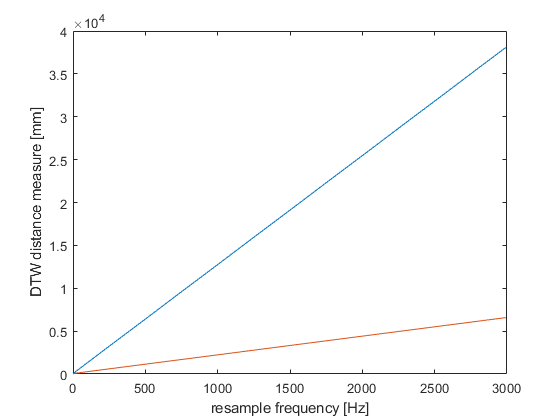

figure
plot(samp_f_vec, DTW_Measures(1,:), samp_f_vec, DTW_Measures(2,:))
xlabel('resample frequency [Hz]')
ylabel('DTW distance measure [mm]')